clear all;

fig=gcf;
fig.Position(4)=550;

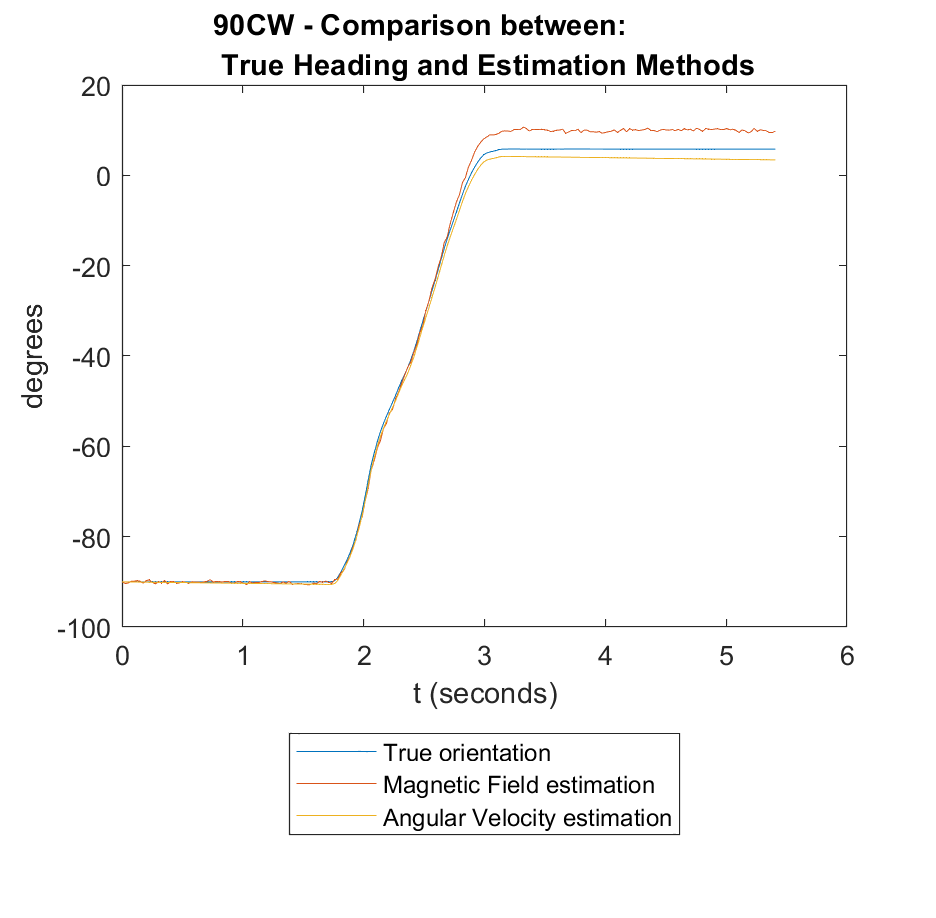

% 90deg clockwise
heading('90CW')

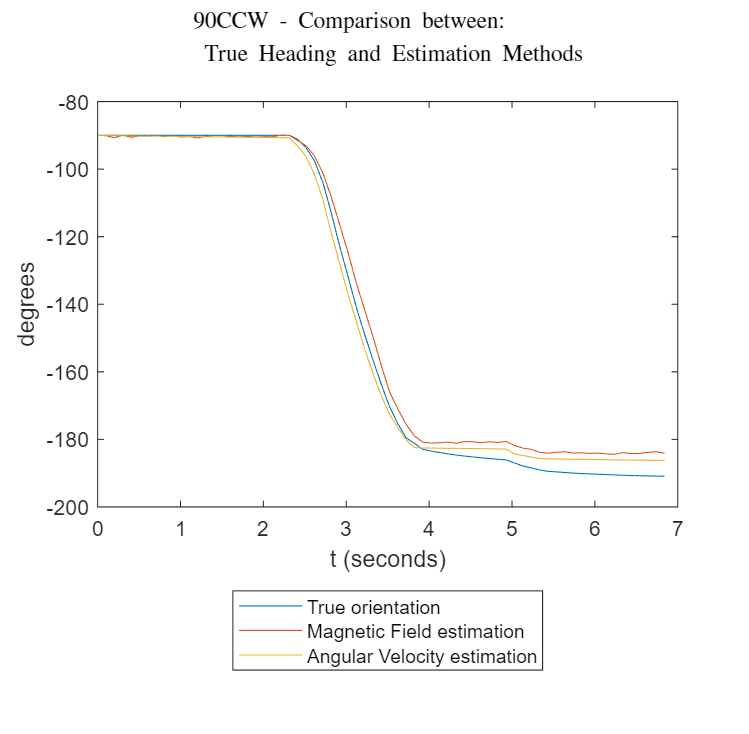

% 90deg counter-clockwise
heading('90CCW')

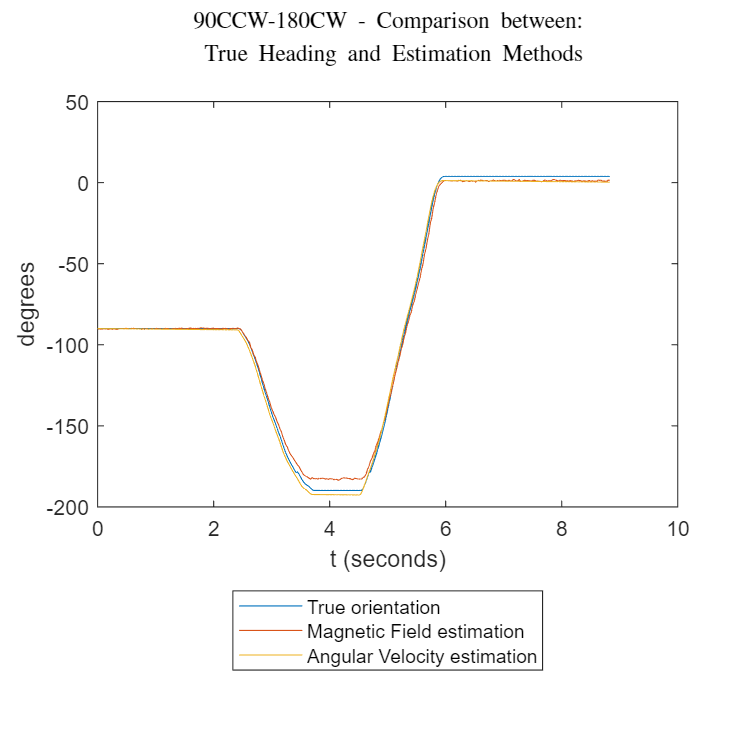

% 90deg counter-clockwise then 180deg clockwise
heading('90CCW-180CW')

function heading(filename)
    data = load(filename+".mat");
    m = data.MagneticField;
    a = data.AngularVelocity;
    o = data.Orientation;
    % a_data = [a.X, a.Y, a.Z];
    m_data = [m.X, m.Y, m.Z];
    % o_data = [o.X, o.Y, o.Z];
    
    t = a.Timestamp.Second - a.Timestamp.Second(1);
    t(t<0) = t(t<0) + 60;
    % Sampling frequency
    f=1/(t(2)-t(1));
    
    % Discontinuity threshold in degrees to unwrap
    thresh = 350;
    
    % True orientation. Phone is facing up, so only X changes
    truth = unwrap(o.X,thresh);
    
    % Magnetometer calibration
    [A,b,~]  = magcal(m_data);
    M = (m_data-b)*A;
    
    % Heading estimation using magnetic field (Only atan2(y,x) changes)
    dm = rad2deg(atan2(M(:,2),M(:,1)));
    mf_est = unwrap(dm,thresh);
    % Remove constant to match with orientation
    mf_est = mf_est - mf_est(1) + truth(1);
    
    % Heading estimation using angular velocity (Only Z changes)
    da = rad2deg(cumsum(-a.Z/f));
    av_est = da+mf_est(1);
    
    % Comparison plot
    plot(t,[truth, mf_est, av_est]);
    legend('True orientation','Magnetic Field estimation','Angular Velocity estimation','location','southoutside');
    title(append(filename,' - Comparison between:\newline True Heading and Estimation Methods\newline'));
    xlabel('t (seconds)');
    ylabel('degrees');
    print(append(filename,'_estimation_comparison.png'),'-dpng');
end